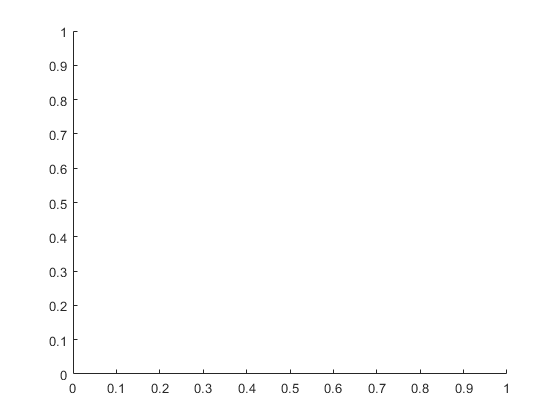

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%                                                   %%%%%%%%%%%%%%
%%%%%%%%%%   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   %%%%%%%%%%%
%%%%%%%%%%%   %                                            %%%%%   %%%%%%%%
%%%%%%%%%%%   %                                              %%%%%   %%%%%%
%%%%%%%%%%%%   %                                             %%%%%%%   %%%%
%%%%%%%%%%%%   %                                             %%%%%%%%   %%%
%%%%%%%%%%%%%   %%%%%%%%%%%%%%%%    %%%%%%%%%%%%            %%%%%%%%%   %%%
%%%%%%%%%%%%%%%    %%%%%%%         %%%%%%%%%%              %%%%%%%%%   %%%%
%%%%%%%%%%%%%%%%%%   %            %%%%%%%                 %%%%%%%%%   %%%%%
%%%%%%%%%%%%%%%%%   %            %%%%                    %%%%%%%%%   %%%%%%
%%%%%%%%%%%%%%%%   %            %                     %%%%%%%%%%%   %%%%%%%
%%%%%%%%%%%%%%%   %                                %%%%%%%%%%%   %%%%%%%%%%
%%%%%%%%%%%%%%   %                              %%%%%%%%%%%   %%%%%%%%%%%%%
%%%%%%%%%%%%%   %             %                    %%%%   %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%   %             %%%%%                  %%%%%%   %%%%%%%%%%%%%%
%%%%%%%%%%%   %             %%%%%%%                 %%%%%%%%   %%%%%%%%%%%%
%%%%%%%%%%   %             %%%%%%%%%               %%%%%%%%%%   %%%%%%%%%%%
%%%%%%%%%   %             %%%%%%%%%%              %%%%%%%%%%%   %%%%%%%%%%%
%%%%%%%%   %             %%%%%%%%%               %%%%%%%%%%%   %%%%%%%%%%%%
%%%%%%%   %                                     %%%%%%%%%%%   %%%%%%%%%%%%%
%%%%%%   %                                     %%%%%%%%%%%   %%%%%%%%%%%%%%
%%%%%   %                                     %%%%%%%%%%%   %%%%%%%%%%%%%%%
%%%%   %                                   %%%%%%%%%%%%%   %%%%%%%%%%%%%%%%
%%%   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   %%%%%%%%%%%%%%%%%
%%%%   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   %%%%%%%%%%%%%%%%%%%
%%%%%   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   %%%%%%%%%%%%%%%%%%%%
%%%%%%   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%                                            %%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Stuart Shepard %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%% Binghamton University %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 2015 - 2020 %%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% VASP - DENSITY OF STATES PLOTTER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% DESCRIPTION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This script can be used to read in a general DOSCAR file output from VASP 
% and organize data into arrays for plotting or saving to .mat files to 
% plot outside this script. 'General' includes non-spin polarized, 
% collinear spin-polarized, and noncollinear spin-polarized calculations 
% with or without projected density of states (PDOS) written to the DOSCAR 
% file.
%
% Specify the VASP DOSCAR-format file name on line 83
%
% The total density of states (DOS) plotting option section is marked
% clearly in the script. Similarly for the PDOS plotting option section.
%
%
% If PDOS data is present  in the file you can choose whether or not to 
% parse and plot it by looking at line ### and making the appropriate 
% changes explained there.
%
% Since the array size for the PDOS of large systems can become very
% large you have the option to parse and store only specific PDOS site
% (atom) data. This can be done manually on line ####. Unfortunately, the
% DOSCAR output does not contain atom type / order information, so you will
% have to enter atom numbers using the information from the POSCAR/CONTCAR
% file.
%
% The PDOS plotting options section is made visible and is left open ended.
% Examples are provided.


clear
cla reset
hold on;

## Getting DOSCAR Information

file = 'DOSCAR';
fid = fopen(file);
line = fscanf(fid,'%i'); num_atoms = line(2); projected = line(3); % line 1
line = fscanf(fid,'%f %f %f %f %f',5); vol = line(1); % line 2
line = fgetl(fid); line = fgetl(fid); line = fgetl(fid); line = fgetl(fid); % line 2-6
line = fscanf(fid,'%f %f %f %f %f',5); % line 7
emax = line(1); emin = line(2); num_energy_pts = line(3); fermi = line(4);
line = fgetl(fid); line = fgetl(fid); % line 8-9
tot_cols = strsplit(line, ' ');
num_tot_cols = length(tot_cols) - 1;

if num_tot_cols == 3
    type = 'non spin-polarized or noncollinear spin-polarized';
elseif num_tot_cols ==5
    type = 'collinear spin-polarized';
end

% checking how many columns are in PDOS if projected
if projected == 1  && strcmp(type,'non spin-polarized or noncollinear spin-polarized') % LORBIT = 11
    for i=1:num_energy_pts+1
        line = fgetl(fid); % first line of data of PDOS
    end
    proj_cols = strsplit(line,' ');
    num_proj_cols = length(proj_cols) - 1;
    if num_proj_cols == 10
        type = 'projected non spin-polarized';
    elseif num_proj_cols == 37
        type = 'projected noncollinear spin-polarized';
    end
elseif projected == 1 && strcmp(type,'collinear spin-polarized')
    num_proj_cols = 19;
    type = 'projected collinear spin-polarized';
end
clear tot_cols proj_cols line

fprintf('DOSCAR file contains %s density of states data.\n',type);

DOSCAR file contains projected non spin-polarized density of states data.


fclose(fid);
fid = fopen('DOSCAR');
fgetl(fid); fgetl(fid); fgetl(fid); fgetl(fid); fgetl(fid); block = fgetl(fid); % lines 1-6

fstr = "%f ";
fstr_tot = join(repelem(fstr,num_tot_cols));


## Getting Total DOS data and plotting

dos = zeros(num_energy_pts,num_tot_cols);
for i=1:num_energy_pts
    dos(i,:) = fscanf(fid,fstr_tot,num_tot_cols);
end
fclose(fid);
clear fstr fstr_tot

% data DOSCAR is in states/eV, dividing by unit cel vol. to get states/eV/unit cell
fprintf('Plotting Total Density of States in units of states/eV/unit cell.\n');

Plotting Total Density of States in units of states/eV/unit cell.


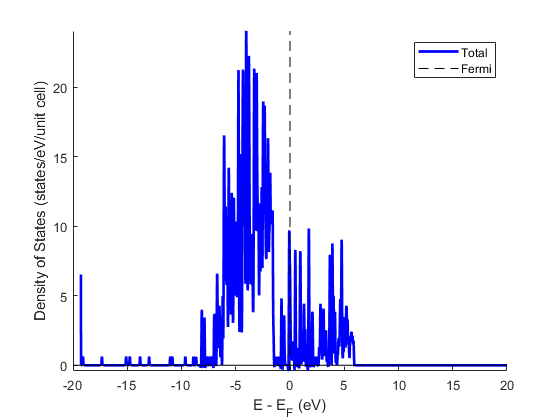


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% EDIT TOTAL DOS PLOT HERE  (SPIN 1) %%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tot_up = plot(dos(:,1)-fermi, dos(:,2)./vol,'b','Linewidth',2);
zero = plot([emin emax],[0 0],'k');
fermilvl = plot([0 0], [min(dos(:,2))/vol max(dos(:,2))/vol],'--k','Linewidth',0.5);
xlim([emin emax]);
ylim([min(dos(:,2))/vol max(dos(:,2))/vol]);
xlabel('E - E_{F} (eV)')
ylabel('Density of States (states/eV/unit cell)')
line_labels = {'Total','Fermi'};
to_plot = [tot_up, fermilvl];
legend([to_plot],line_labels);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% plotting total DOS of opposite spin if spin-polarized
if strcmp(type,'projected spin-polarized') | strcmp(type,'spin-polarized')
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%% EDIT TOTAL DOS PLOT HERE  (SPIN 2) %%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    tot_dn = plot(dos(:,1)-fermi, -1*dos(:,3)./vol,'r','Linewidth',2);
    ylim([-1*max(dos(:,3))/vol max(dos(:,2))/vol]);
    line_labels = {'Total Spin 1','Total Spin 2','Fermi'};
    to_plot = [tot_up tot_dn fermilvl];
    legend(to_plot,line_labels);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end


## PDOS SWITCH ON/OFF SECTION

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TO STOP PDOS READ BELOW %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The code from here on parses and plots the PDOS data.
%
% If there IS PDOS data the code will automatically continue.
% If there IS NOT PDOS data the code will automatically stop.
% AS LONG AS THE VARIABLE 'project' BELOW IS SET EQUAL TO
% THE VARIABLE 'projected'.
%
% IN THE CASE WHERE THERE IS PDOS DATA IN YOUR DOSCAR 
% BUT YOU WISH TO NOT PARSE THE PDOS DATA,
% MANUALLY SET THE VARIABLE 'project' BELOW TO 0.
%
project = projected;
if project == 0
    return % stops code
end
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear dos project projected


## Getting and plotting PDOS data

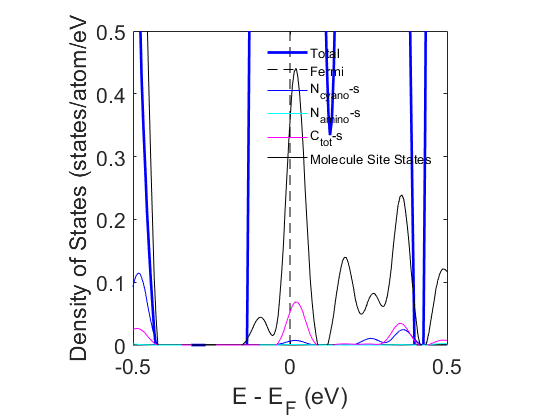

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This is for LORBIT = 11 
% This decomposes the DOS into atomic site, l (total orbital angular momentum), 
% and m (projected orbital angular momentum).
%
% For ISPIN = 2 (collinear spin), the above is decomposed into up and down
% spin components as well.
%
% For LNONCOLLINEAR = True (noncollinear spin) the above is decomposed into
% mx,my,mz spin components. Note including spin orbit coupling (LSORBIT =
% True) automatically turns on noncollinear spin.
%
% Below are the templates for how the PDOS data is organized in each type
% of calculation. For quick reference in plotting PDOS, the numbers
% corresponding to the array data in the 'pdos' variable are shown above
% each decomposition.
%
% NON-SPIN-POLARIZED site projected data is organized in 10 columns as,
% atom 1         (1) (2)  (3)  (4)  (5)   (6)   (7)        (8)   (9) <-column numbers in the pdos variable
% energy point : s : py : pz : px : dxy : dyz : d(z2-r2) : dxz : d(x2-y2)
% ...
% ...
% atom 2
% energy point : ...
% ...
%
% COLLINEAR SPIN-POLARIZED site projected data is organized in 19 columns as,
% atom 1   (1)      (2)        (3)       (4)         (5)       (6)         (7)       (8)         (9)        (10)         (11)       (12)         (13)            (14)              (15)       (16)        (17)            (18)
% energy : s (up) : s (down) : py (up) : py (down) : pz (up) : pz (down) : px (up) : px (down) : dxy (up) : dxy (down) : dyz (up) : dyz (down) : d(z2-r2) (up) : d(z2-r2) (down) : dxz (up) : dxz(down) : d(x2-y2) (up) : d(x2-y2) (down)
% ...
%
% NONCOLLINEAR SPIN-POLARIZED site projected data is organized in 37 columns as,
% atom 1   (1)       (2)    (3)    (4)    (5)        (6)     (7)     (8)     (9)        (10)    (11)    (12)    (13)       (14)    (15)    (16)    (17)        (18)     (19)     (20)     (21)        (22)     (23)     (24)     (25)             (26)          (27)          (28)          (29)        (30)     (31)     (32)     (33)             (34)          (35)          (36)
% energy : s-total : s-mx : s-my : s-mz : py-total : py-mx : py-my : py-mz : pz-total : pz-mx : pz-my : pz-mz : px-total : px-mx : px-my : px-mz : dxy-total : dxy-mx : dxy-my : dxy-mz : dyz-total : dyz-mx : dyz-my : dyz-mz : d(z2-r2)-total : d(z2-r2)-mx : d(z2-r2)-my : d(z2-r2)-mz : dxz-total : dxz-mx : dxz-my : dxz-mz : d(x2-y2)-total : d(x2-y2)-mx : d(x2-y2)-my : d(x2-y2)-mz
% ...
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% SPECIFY ATOMS TO STORE AND PLOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Data can be very large. Getting all data could be difficult 
% especially for large systems and collinear and noncollinear 
% spin-polarized systems.
%
% Right now set up for specific atoms, can save data manually for 
% plotting purposes since DOSCAR does not contain atom type data must 
% enter line numbers to specify which atoms.
%

%HMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM?
%HMM THINKING SPACE MMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM?
%HMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM?
% Specifically looking at DMABN between Au electrodes
% Au 1:256   (256)
% N 257:258  (2)
% C 259:267  (9)
% H 268:277  (10)
% 
% H's not shown
%     
%            (123)  (261)  (266)   (267)         (145)
%  (flat side) Au      C       C - C              Au (tip side)
%                  \    \    //     \\           /
%     (:)N - C--->    (:)N - C       C - C=-N(:)    <---C - C=-N(:)
%     (258)(264)        /     \     /                (265)(259)(257)
%                      C       C = C
%                   (260)  (263)   (262)
%
% Looking at just the molecule atoms subtract 256 from the numbers above

N_CH3 = 258 - 256;
N_CN = 257 - 256;
C_start = 259 - 256;
C_end = 267 - 256;

%HMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM?
%HMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM?
%HMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMMM?
%
sites = [257:num_atoms]; % set equal to [],  or just [1:num_atoms] if you want all data.
if isempty(sites)
    sites = [1:num_atoms];
end
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% getting header line numbers
content = fileread(file);
blockEnds = strfind(content,block); % char num at block start
blockStarts = blockEnds(2:end) + length(block) + 1; % first one is for total DOS
blockEndLast = length(content); % last line of file
blockEnds = [blockEnds(3:end) blockEndLast]; % end lines of pdos sections
blockStarts = blockStarts(sites);
blockEnds = blockEnds(sites);
nSites = numel(blockStarts);

% collecting PDOS of specified sites
pdos = zeros(nSites,num_energy_pts,num_proj_cols);
for i=1:nSites
    pdos(i,:,:) = reshape(sscanf(content(blockStarts(i):blockEnds(i)),'%f'),num_proj_cols,[])';
end

clear content i sites fid

% energy points are saved redundantly
en = pdos(1,:,1);
pdos = pdos(:,:,2:end); % removing multiple saves of energy points

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% PDOS PLOTTING SECTION %%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plotting PDOS data in states/atom/eV
% use template shown above to plot what you are interested in
% NOTE: the energy column has been removed from the pdos array.

% Example, pz character on atomic site 1
N_CN_pz = plot(en - fermi,pdos(N_CN,:,1), 'b'); % just store plot as variable
ylabel('Density of States (states/atom/eV');
xlim([-0.5 0.5]); % will override previous limits
ylim([0 0.5]);
to_plot = [to_plot N_CN_pz]; % add new plot to this variable as shown
line_labels{end+1} = 'N_{cyano}-s'; % add the label you wish to see in the legend for this plot here.

% N-pz on dimethyl side
N_CH3_pz = plot(en - fermi,pdos(N_CH3,:,1), 'c');
to_plot = [to_plot N_CH3_pz];
line_labels{end+1} = 'N_{amino}-s';

% Total carbon pz
C_tot = sum(pdos(C_start:C_end,:,:),1);
C_tot = squeeze(C_tot);
C_tot_pz = plot(en - fermi,C_tot(:,1), 'm');
to_plot = [to_plot C_tot_pz];
line_labels{end+1} = 'C_{tot}-s';

% Example, total dos of selection and saving data for plotting
tot_sel = sum(pdos,1);
tot_sel = sum(tot_sel,3);
tot_mol = plot(en - fermi, tot_sel,'k'); % saving plot
to_plot = [to_plot tot_mol]; % adding plot to array of plots
line_labels{end+1} = 'Molecule Site States'; % adding label for current plot to list of legend labels
%save molecule_total_dos tot_sel -mat; % saving to plot outside of script
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% GENERAL PLOTTING OPTIONS %%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

set(gca,'Fontsize',16);
pbaspect([1 1 1]);
box on;
legend(to_plot,line_labels,'FontSize',10); % plotting with legend / legend properties
legend box off;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
